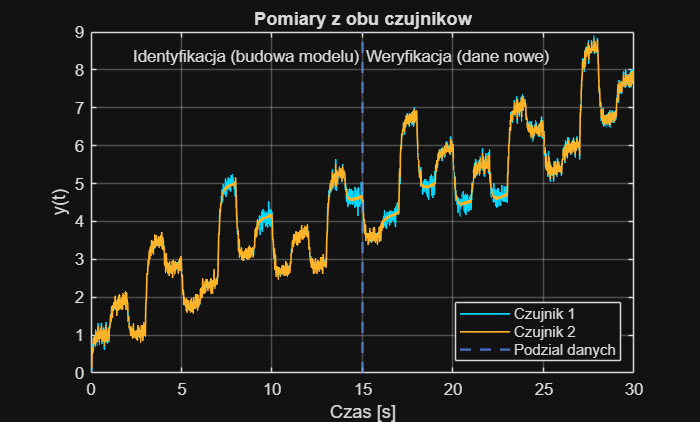

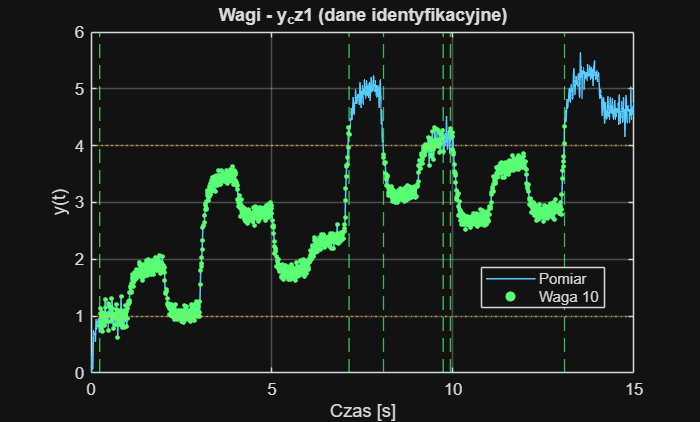

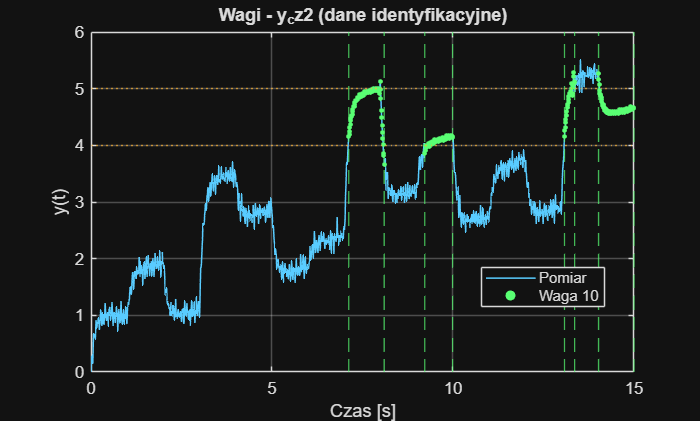


===== Czujnik 1 =====
    method       a          b         mean_rep     mse_rep     var_rep     mean_pred    mse_pred    var_pred
    ______    _______    ________    __________    ________    ________    _________    ________    ________

    "MNK"     0.87047    0.051586    0.00070317    0.011612    0.011619    0.020813     0.024627     0.02421
    "W10"     0.88313    0.046463     0.0015417    0.011634     0.01164    0.032611     0.021186    0.020136
    "W50"     0.88453    0.045895     0.0016425     0.01164    0.011645    0.034209     0.020879    0.019722
    "W100"    0.88471    0.045823     0.0016556     0.01164    0.011645    0.034418     0.020841    0.019669

MNK: G(z) = 0.0

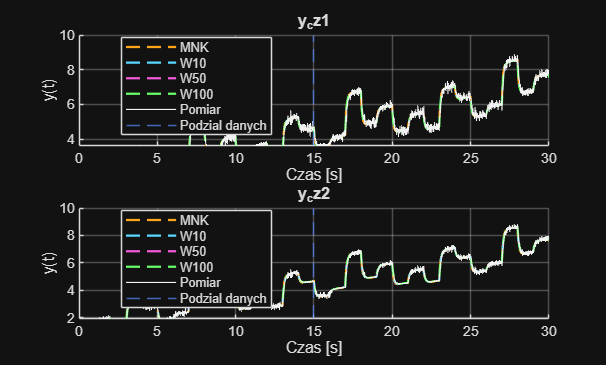

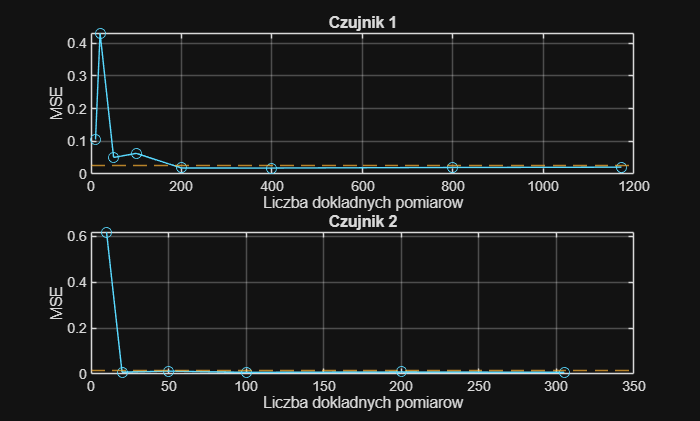


Wystarczajaca liczba pomiarow (MSE <= 1.05 * MSE_MNK):
Czujnik 1: 200
Czujnik 2: 20


clear; clc; close all;

%% SETUP
Work_data = load('MiI_P1_grupa_1b.mat');
[sr, time, I_Data, V_Data] = Setup(Work_data);

% Parametry klasyfikacji
avg_window = 21;
tol = 0.1;
gains = [10 50 100];

[I_Data, V_Data] = weight_creator(I_Data, V_Data, gains(1), avg_window, tol);

%% OBLICZENIA
[Models_sensor1, Test_sensor1] = model_estimation(I_Data, V_Data, time, sr, 'y_cz1', gains);
[Models_sensor2, Test_sensor2] = model_estimation(I_Data, V_Data, time, sr, 'y_cz2', gains);

%% WYNIKI
present_results(time, I_Data, V_Data, Models_sensor1, Models_sensor2, Test_sensor1, Test_sensor2, gains, sr);



%% =========================================================
% Funkcje matematyczne
%% =========================================================

function [Models, Test] = model_estimation(I_Data, V_Data, time, sr, sensor_name, gains)

    % Macierz regresji i wektor obserwacji
    [H, Y, base_weights] = regression_creator(I_Data, sensor_name);
    mask = base_weights > 1;
    N_est = size(I_Data.u, 1);

    % MNK oraz trzy warianty WMNK
    for i = 1:length(gains)+1

        if i == 1
            weights = ones(size(Y));
            model_name = 'MNK';
        else
            weights = 1 + (gains(i-1)-1) * double(mask);
            model_name = sprintf('W%d', gains(i-1));
        end

        W = diag(weights);
        x = (H' * W * H) \ (H' * W * Y);

        % Transmitancja dyskretna i weryfikacja
        G = tf(x(2), [1 -x(1)], sr, 'Variable', 'z^-1');
        Verification = model_verification(V_Data, sensor_name, x, N_est, time, G);

        Models(i).name = model_name;
        Models(i).x = x;
        Models(i).G = G;
        Models(i).verification = Verification;
    end

    % Estymacja tylko na dokladniejszych probkach
    Test = precise_test(H, Y, mask, V_Data, sensor_name, N_est, ...
        time, sr, Models(1).verification.predykatywna.MSE);
end

function [H, Y, weights] = regression_creator(I_Data, sensor_name)

    % Pomiar i waga obserwacji
    sensor_data = I_Data.(sensor_name);
    y = sensor_data(:,1);
    weights = sensor_data(2:end,2);
    u = I_Data.u(:);

    % y(k) = a*y(k-1) + b*u(k)
    H = [y(1:end-1), u(2:end)];
    Y = y(2:end);
end

function Verification = model_verification(V_Data, sensor_name, x, N_est, time, G)

    y = V_Data.(sensor_name);
    y = y(:,1);
    u = V_Data.u(:);

    % Prognoza jednokrokowa
    Y_model = [y(1); x(1)*y(1:end-1) + x(2)*u(2:end)];

    % Odpowiedz swobodna przez lsim z warunkiem poczatkowym
    Y_zero = lsim(G, u(2:end), time(1:end-1));
    Y_sim = [y(1); Y_zero(:) + y(1)*x(1).^(1:length(y)-1)'];

    % Bledy na danych estymacyjnych i nowych
    e_one = y - Y_model;
    e_sim = y - Y_sim;

    Verification.replikatywna = error_metrics(e_one(2:N_est));
    Verification.predykatywna = error_metrics(e_sim(N_est+1:end));
    Verification.calosc = error_metrics(e_sim(2:end));
    Verification.Y_model = Y_model;
    Verification.Y_sim = Y_sim;
end

function Metrics = error_metrics(residuals)
    Metrics.mean_error = mean(residuals);
    Metrics.MSE = mean(residuals.^2);
    Metrics.variance = var(residuals, 0);
end

function Test = precise_test(H, Y, mask, V_Data, sensor_name, N_est, time, sr, MSE_MNK)

    precise_idx = find(mask);
    N = length(precise_idx);
    counts = unique([10 20 50 100 200 400 800 N]);
    counts = counts(counts >= 2 & counts <= N);

    Test.counts = counts;
    Test.MSE = NaN(size(counts));
    Test.limit = 1.05 * MSE_MNK;
    Test.N_enough = NaN;

    for i = 1:length(counts)
        selected = precise_idx(round(linspace(1, N, counts(i))));
        x = H(selected,:) \ Y(selected);
        G = tf(x(2), [1 -x(1)], sr, 'Variable', 'z^-1');
        Verification = model_verification(V_Data, sensor_name, x, N_est, time, G);
        Test.MSE(i) = Verification.predykatywna.MSE;
    end

    idx = find(Test.MSE <= Test.limit, 1, 'first');
    if ~isempty(idx)
        Test.N_enough = counts(idx);
    end
end


%% =========================================================
% Funkcje poboczne
%% =========================================================

function [I_Data, V_Data] = weight_creator(I_Data, V_Data, w_max, avg_window, tol)

    % Zakresy wiekszej dokladnosci (grupa 1b)
    sensors = {'y_cz1', 'y_cz2'};
    ranges = [1 4; 4 5];
    Data = {I_Data, V_Data};

    for k = 1:length(Data)
        temp_data = Data{k};

        for i = 1:length(sensors)
            name = sensors{i};
            y = temp_data.(name);
            y = y(:,1);

            % Wygladzenie tylko do klasyfikacji
            y_avg = movmean(y, avg_window);
            mask = (y_avg >= ranges(i,1)-tol) & ...
                   (y_avg <= ranges(i,2)+tol);

            % Wagi 1 lub w_max; oryginalny pomiar bez zmian
            weights = 1 + (w_max-1) * double(mask);
            temp_data.(name) = [y, weights];
        end

        Data{k} = temp_data;
    end

    I_Data = Data{1};
    V_Data = Data{2};
end


%% =========================================================
% Prezentacja danych
%% =========================================================

function present_results(time, I_Data, V_Data, Models_sensor1, Models_sensor2, Test_sensor1, Test_sensor2, gains, sr)

    % 1. Oba pomiary i podzial danych
    plot_measurements(time, I_Data, V_Data);

    % 2. Pomiary i klasyfikacja wag dla obu czujnikow
    plot_weights(time, I_Data, 'y_cz1', [1 4]);
    plot_weights(time, I_Data, 'y_cz2', [4 5]);

    % 3. Parametry, transmitancje i wskazniki bledow
    print_results(Models_sensor1, Models_sensor2, sr);

    % 4. Porownanie modeli z pomiarami
    plot_models(time, I_Data, V_Data, Models_sensor1, Models_sensor2, gains);

    % 5. Liczba dokladnych pomiarow
    plot_precise(Test_sensor1, Test_sensor2);
end

function plot_measurements(time, I_Data, V_Data)

    N_est = size(I_Data.u, 1);
    figure('Name', 'Pomiary - oba czujniki');

    plot(time, V_Data.y_cz1(:,1), 'Color', [0.0 0.85 1.0], 'LineWidth', 1.0);
    hold on;
    plot(time, V_Data.y_cz2(:,1), 'Color', [1.0 0.70 0.15], 'LineWidth', 1.0);
    xline(time(N_est), '--', 'Color', [0.35 0.55 1.0], 'LineWidth', 1.5);

    grid on;
    xlim([time(1) time(end)]);
    xlabel('Czas [s]');
    ylabel('y(t)');
    title('Pomiary z obu czujnikow');
    legend('Czujnik 1', 'Czujnik 2', 'Podzial danych', 'Location', 'southeast');

    limits = ylim;
    label_height = limits(2) - 0.07 * diff(limits);
    axis_color = get(gca, 'XColor');
    text(time(N_est)-0.2, label_height, 'Identyfikacja (budowa modelu)', ...
        'HorizontalAlignment', 'right', 'Color', axis_color);
    text(time(N_est)+0.2, label_height, 'Weryfikacja (dane nowe)', ...
        'HorizontalAlignment', 'left', 'Color', axis_color);
end

function plot_weights(time, I_Data, sensor_name, range)

    sensor_data = I_Data.(sensor_name);
    y = sensor_data(:,1);
    weights = sensor_data(:,2);
    t = time(1:length(y));
    mask = weights > 1;

    figure('Name', ['Wagi - ' sensor_name]);
    plot(t, y, 'Color', [0.35 0.8 1.0], 'LineWidth', 0.9);
    hold on;
    scatter(t(mask), y(mask), 8, [0.35 1.0 0.45], 'filled');

    % Przerywane linie wyznaczaja przedzialy z wyzsza waga
    changes = find(diff([false; mask; false]));
    for i = 1:2:length(changes)
        start_idx = changes(i);
        end_idx = changes(i+1)-1;
        xline(t(start_idx), '--', 'Color', [0.35 1.0 0.45], 'LineWidth', 0.8);
        xline(t(end_idx), '--', 'Color', [0.35 1.0 0.45], 'LineWidth', 0.8);
    end

    yline(range(1), ':', 'Color', [1.0 0.7 0.2]);
    yline(range(2), ':', 'Color', [1.0 0.7 0.2]);
    xlim([t(1) t(end)]);
    grid on;
    xlabel('Czas [s]');
    ylabel('y(t)');
    title(['Wagi - ' sensor_name ' (dane identyfikacyjne)']);
    legend('Pomiar', sprintf('Waga %g', max(weights)), 'Location', 'best');
end

function print_results(Models_sensor1, Models_sensor2, sr)

    Data = {Models_sensor1, Models_sensor2};
    names = {'Czujnik 1', 'Czujnik 2'};

    for s = 1:2
        Models = Data{s};
        method = string({Models.name})';
        a = arrayfun(@(m) m.x(1), Models)';
        b = arrayfun(@(m) m.x(2), Models)';
        mean_rep = arrayfun(@(m) m.verification.replikatywna.mean_error, Models)';
        mse_rep = arrayfun(@(m) m.verification.replikatywna.MSE, Models)';
        var_rep = arrayfun(@(m) m.verification.replikatywna.variance, Models)';
        mean_pred = arrayfun(@(m) m.verification.predykatywna.mean_error, Models)';
        mse_pred = arrayfun(@(m) m.verification.predykatywna.MSE, Models)';
        var_pred = arrayfun(@(m) m.verification.predykatywna.variance, Models)';

        fprintf('\n===== %s =====\n', names{s});
        Results = table(method, a, b, mean_rep, mse_rep, var_rep, ...
            mean_pred, mse_pred, var_pred);
        disp(Results);

        for i = 1:length(Models)
            a0 = (1 - Models(i).x(1)) / (Models(i).x(1)*sr);
            b0 = Models(i).x(2) / (Models(i).x(1)*sr);
            fprintf('%s: G(z) = %.6f / (1 - %.6f z^-1), G(s) = %.6f / (s + %.6f)\n', ...
                Models(i).name, Models(i).x(2), Models(i).x(1), b0, a0);
        end
    end
end

function plot_models(time, I_Data, V_Data, Models_sensor1, Models_sensor2, gains)

    figure('Name', 'Modele i pomiary');
    Data = {Models_sensor1, Models_sensor2};
    sensors = {'y_cz1', 'y_cz2'};
    model_colors = [1.0 0.65 0.10; 0.35 0.85 1.0; 0.95 0.35 0.85; 0.40 1.0 0.40];

    for s = 1:2
        subplot(2,1,s);
        hold on;
        Models = Data{s};

        for i = 1:length(Models)
            plot(time, Models(i).verification.Y_sim, '--', ...
                'Color', model_colors(i,:), 'LineWidth', 1.35);
        end

        sensor_data = V_Data.(sensors{s});
        plot(time, sensor_data(:,1), '-', ...
            'Color', [0.95 0.95 0.95], 'LineWidth', 0.65);
        xline(time(size(I_Data.u,1)), '--', 'Color', [0.35 0.55 1.0]);

        grid on;
        xlim([time(1) time(end)]);
        title(sensors{s});
        xlabel('Czas [s]');
        ylabel('y(t)');
        legend('MNK', sprintf('W%d',gains(1)), sprintf('W%d',gains(2)), ...
            sprintf('W%d',gains(3)), 'Pomiar', 'Podzial danych', ...
            'Location', 'best');
    end
end

function plot_precise(Test_sensor1, Test_sensor2)

    Data = {Test_sensor1, Test_sensor2};
    figure('Name', 'Liczba dokladnych probek');

    for s = 1:2
        subplot(2,1,s);
        Test = Data{s};
        plot(Test.counts, Test.MSE, '-o', 'Color', [0.35 0.85 1.0]);
        hold on;
        yline(Test.limit, '--', 'Color', [1.0 0.7 0.2]);
        grid on;
        xlabel('Liczba dokladnych pomiarow');
        ylabel('MSE');
        title(sprintf('Czujnik %d', s));
    end

    fprintf('\nWystarczajaca liczba pomiarow (MSE <= 1.05 * MSE_MNK):\n');
    fprintf('Czujnik 1: %g\n', Test_sensor1.N_enough);
    fprintf('Czujnik 2: %g\n', Test_sensor2.N_enough);
end


%% =========================================================
% Funkcje pomocnicze
%% =========================================================

%% Setup - usuwa metadane, upraszcza struktury i dzieli dane
function [sr, time, I_Data, V_Data] = Setup(Work_data)
    sr = Work_data.td;
    temp_data = rmfield(Work_data, 'td');

    temp_names = fieldnames(temp_data);
    for i = 1:length(temp_names)
        temp_data.(temp_names{i,1}) = struct_deconstructor(temp_data.(temp_names{i,1}));
    end

    [time_data, temp_data] = seek_and_destroy('time', temp_data);
    time = time_data(1).value;
    temp_data = struct_rearranger(temp_data);
    V_Data = temp_data;

    N = floor(length(time)/2) + 1;
    I_Data = temp_data;
    temp_names = fieldnames(I_Data);
    for i = 1:length(temp_names)
        name = temp_names{i};
        temp_values = I_Data.(name);
        I_Data.(name) = temp_values(1:N,:);
    end
end

%% Struct deconstructor - rekurencyjnie usuwa zbedne pola
function Temp_data = struct_deconstructor(Data)
    if isstruct(Data)
        temp_names = fieldnames(Data);
        for i = 1:length(temp_names)
            field_name = temp_names{i,1};
            current_field = Data.(field_name);
            if isstruct(current_field)
                Data.(field_name) = struct_deconstructor(current_field);
            elseif length(current_field) <= 1 || ischar(current_field)
                Data = rmfield(Data, field_name);
            end
        end
    end
    Temp_data = Data;
end

%% Seek and destroy - rekurencyjnie wyszukuje i usuwa wskazane pola
function [targets, Data_O] = seek_and_destroy(target_name, Data_I, prefix)
    if nargin < 3
        prefix = '';
    end
    targets = struct('path', {}, 'value', {});
    Data_O = Data_I;
    if ~isstruct(Data_I) || isempty(Data_I)
        return;
    end
    names = fieldnames(Data_I);
    for k = 1:numel(Data_I)
        local_prefix = prefix;
        if numel(Data_I) > 1
            local_prefix = sprintf('%s(%d)', prefix, k);
        end
        for i = 1:numel(names)
            name = names{i};
            value = Data_I(k).(name);
            if isempty(local_prefix)
                current_path = name;
            else
                current_path = [local_prefix '.' name];
            end
            if strcmp(name, target_name)
                targets(end+1) = struct('path', current_path, 'value', value);
            end
            if isstruct(value)
                [found, new_value] = seek_and_destroy(target_name, value, current_path);
                targets = [targets, found];
                if ~strcmp(name, target_name)
                    Data_O(k).(name) = new_value;
                end
            end
        end
    end
    if isfield(Data_O, target_name)
        Data_O = rmfield(Data_O, target_name);
    end
end

%% Struct rearranger - rekurencyjnie splaszcza zagniezdzone struktury
function Temp_data = struct_rearranger(Data)
    if ~isstruct(Data) || isempty(Data)
        Temp_data = Data;
        return;
    end
    names = fieldnames(Data);
    if numel(Data) > 1
        Temp_data = Data;
        for k = 1:numel(Data)
            for i = 1:numel(names)
                name = names{i};
                Temp_data(k).(name) = struct_rearranger(Data(k).(name));
            end
        end
        return;
    end
    for i = 1:numel(names)
        name = names{i};
        Data.(name) = struct_rearranger(Data.(name));
    end
    if numel(names) == 1
        Temp_data = Data.(names{1});
    else
        Temp_data = Data;
    end
end
